# 2. iDMRG (infinite-size Density Matrix Renormalization Group)

Author: 조성주,  최윤식

## Problem

In this project, we are going to implement the infinite-size DMRG (iDMRG) for the anti-ferromagnetic S = 1/2 Heisenberg chain with open boundary conditions,


$$\hat{H}_\text{Heisenberg} = \sum_{\langle ij\rangle} \left[ \hat{{S}}_i^z  \hat{S}_j^z + \frac{1}{2} (\hat{S}_i^+ \hat{S}_j^-+\hat{S}_i^- \hat{S}_j^+) \right],$$


and the Ising model in a transverse field with open boundary conditions,


$$\hat{H}_\text{Ising} = \sum_{\langle ij\rangle}  \hat{{S}}_i^z  \hat{S}_j^z + \lambda\sum_i \hat S_i^x ,$$
				

where $\hat{\;S_i }$ are local spin-1/2 operators on site i. Here we refer to the figures and equations of Ref. 1. 

References			

[1] I. P. McCulloch, [arXiv:0804.2509 (2008)](https://arxiv.org/abs/0804.2509).

[2] S. R. White, [Phys. Rev. Lett. 69, 2863 (1992)](https://journals.aps.org/prl/abstract/10.1103/PhysRevLett.69.2863). 

clear

% iDMRG parameters
Nkeep = 30;
Skeep = 1e-8;
Nsweep = 200;

% model definition
J=1;
lamb = 0.5;  % at critical point of ITF

% Local operators
[S,I] = getLocalSpace('Spin',1/2);

% Hamiltonian in MPO representation
H_MPO = cell(1,2);

% Heisenberg model
Hloc = cell(5,5);
Hloc(:) = {zeros(size(I))};
Hloc{1,1} = I;
for ito = (1:size(S,3)) % different components of spin operators
    Hloc{ito+1,1} = S(:,:,ito);
    Hloc{end,ito+1} = J*S(:,:,ito)';
end
Hloc{end,end} = I;
Hloc = cell2mat(reshape(Hloc,[1 1 size(Hloc,1) size(Hloc,2)]));
H_MPO{1} = Hloc;

% Ising transverse field model

Hloc = cell(5,5);
Hloc(:) = {zeros(size(I))};
Hloc{1,1} = I;
for ito = (1:size(S,3)) % different components of spin operators
    Hloc{ito+1,1} = S(:,:,ito);
end
Hloc{end,3} = S(:,:,2)';  % Sz Ising interaction
Hloc{end,2} = lamb*I/sqrt(2);   % transverse field
Hloc{end,4} = lamb*I/sqrt(2);

Hloc{end,end} = I;
Hloc = cell2mat(reshape(Hloc,[1 1 size(Hloc,1) size(Hloc,2)]));
H_MPO{2} = Hloc;



## Point of Interest

- compare with Vidal's iTEBD : faster convergence because power method is not an efficient eigensolver. And Trotter decomposition requires careful scaling of time-step to zero for convergence.

- advantage of using MPS

- advantage of using MPO

## a)

Implement the iDMRG for translation invariant systems of a two-site unit cell. The procedure is summarized in Fig. 1. 		

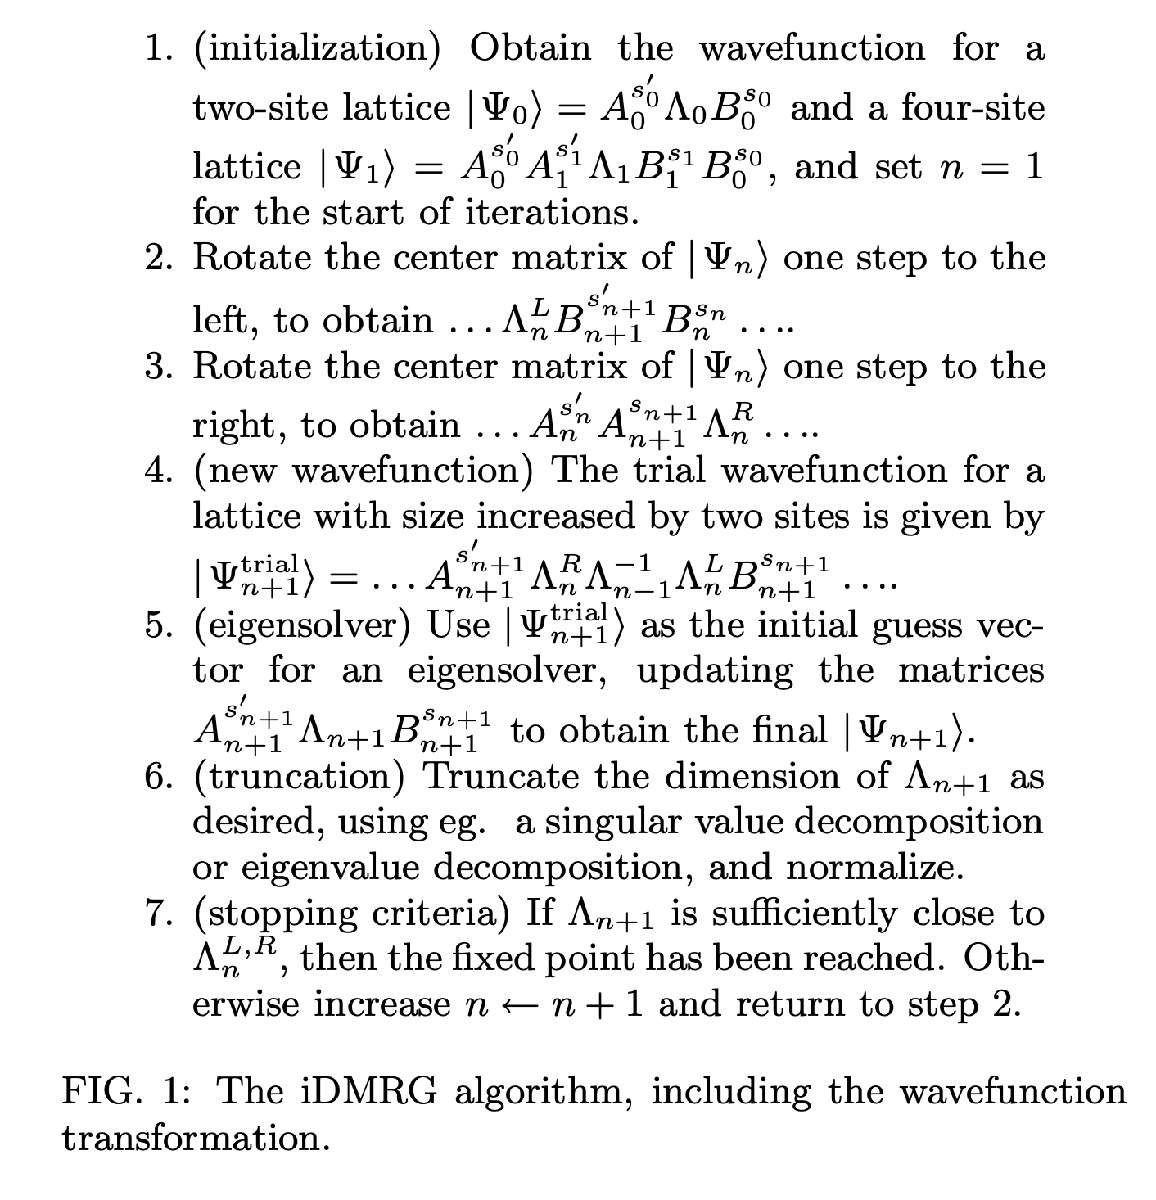		

% prepare outputs
D_list = [20 30 40 50];
Eiters = cell(2,numel(D_list));
Fid_iters = cell(2,numel(D_list));
Spect = cell(2,numel(D_list));

for its = (1:2)
    H_loc = H_MPO{its};

    % prepare system
    Lambda_init = cell(1,2);
    A_init = cell(1,2);
    B_init = cell(1,2);

    

    % step 1. initialize wavefunction with finite size DMRG
    % 2site solution
    Nkeep = 20;
    Minit = cell(1,2);
    Minit{1} = rand(1,Nkeep,size(I,2));
    Minit{end} = rand(Nkeep,1,size(I,2));
    Hs = cell(1,2);
    Hs(:) = {H_loc};
    Hs{1} = Hs{1}(:,:,end,:); % choose the last components of the left leg
    Hs{end} = Hs{end}(:,:,:,1); % choose the first components of the right leg
    
    [~,~,~,Sv] = DMRG_GS_2site(Minit,Hs,Nkeep, Nsweep);
    Lambda_init{1} = Sv{2}/norm(Sv{2});

    % 4site solution
    Minit = cell(1,4);
    Minit{1} = rand(1,Nkeep,size(I,2));
    Minit{end} = rand(Nkeep,1,size(I,2));
    for itN = (2:3)
        Minit{itN} = rand(Nkeep,Nkeep,size(I,2));
    end
    Hs = cell(1,4);
    Hs(:) = {H_loc};
    Hs{1} = Hs{1}(:,:,end,:); % choose the last components of the left leg
    Hs{end} = Hs{end}(:,:,:,1); % choose the first components of the right leg
    
    [M ,~,~,~] = DMRG_GS_2site(Minit,Hs,Nkeep, Nsweep);
    A_init{1} = M{1};
    T = contract(M{3},3,2,M{4},3,1);
    [U,S,B_init{1}] = svdTr(T,4,[1 2],Nkeep,Skeep);
    T = contract(U,3,3,diag(S),2,1, [1 3 2]);
    T = contract(M{2},3,2,T,3,1);
    [A_init{2},Lambda_init{2},B_init{2}] = svdTr(T,4,[1 2],Nkeep,Skeep);
    A_init{2} = permute(A_init{2},[1 3 2]);
    Lambda_init{2} = Lambda_init{2}/norm(Lambda_init{2});


    for itD = (1:numel(D_list))
        Nkeep = D_list(itD)
  
        % 2~7 loop : in function iDMRG_GS.m
        [Lambda,A,B,Eiters{its,itD},Fid_iters{its,itD}] = iDMRG_GS(Lambda_init,A_init,B_init,H_loc,Nkeep,Nsweep);
        
        % Transfer matrix from the resulting wavefunction
        Transfer = contract(A,3,2,diag(Lambda{2}),2,1,[1 3 2]);
        Transfer = contract(Transfer,3,3,conj(Transfer),3,3,[1 3 2 4]);
        Transfer = contract(Transfer,4,3,B,3,1);
        Transfer = contract(Transfer,5,[3 5],conj(B),3,[1 3]);
        Transfer = contract(Transfer,4,3,diag(1./Lambda{1}),2,1);
        Transfer = contract(Transfer,4,3,diag(1./conj(Lambda{1})),2,1);
        % spectrum of Transfer matrix
        [~,Spect{its,itD},~] = svdTr(Transfer,4,[1 2],[],0);

    end
end

22-12-05 23:21:52 | Two-site DMRG: ground state search
22-12-05 23:21:52 | # of sites = 2, Nkeep = 20, # of sweeps = 200 x 2
22-12-05 23:21:52 | Sweep #1/400 (right -> left) : Energy = -0.75
22-12-05 23:21:52 | Sweep #2/400 (left -> right) : Energy = -0.75
22-12-05 23:21:52 | Sweep #3/400 (right -> left) : Energy = -0.75
22-12-05 23:21:52 | Sweep #4/400 (left -> right) : Energy = -0.75
22-12-05 23:21:52 | Sweep #5/400 (right -> left) : Energy = -0.75
22-12-05 23:21:52 | Sweep #6/400 (left -> right) : Energy = -0.75
22-12-05 23:21:52 | Sweep #7/400 (right -> left) : Energy = -0.75
22-12-05 23:21:52 | Sweep #8/400 (left -> right) : Energy = -0.75
22-12-05 23:21:52 | Sweep #9/400 (right -> left) : Energy = -0.75
22-12-05 23:21:52 | Sweep #10/400 (left -> right) : Energy = -0.75
22-12-05 23:21:52 | Sweep #11/400 (right -> left) : Energy = -0.75
22-12-05 23:21:52 | Sweep #12/400 (left -> right) : Energy = -0.75
22-12-05 23:21:52 | Sweep #13/400 (right -> left) : Energy = -0.75
22-12-05 23:2

22-12-05 23:21:52 | Two-site DMRG: ground state search
22-12-05 23:21:52 | # of sites = 4, Nkeep = 20, # of sweeps = 200 x 2
22-12-05 23:21:52 | Sweep #1/400 (right -> left) : Energy = -1.616025
22-12-05 23:21:52 | Sweep #2/400 (left -> right) : Energy = -1.616025
22-12-05 23:21:52 | Sweep #3/400 (right -> left) : Energy = -1.616025
22-12-05 23:21:52 | Sweep #4/400 (left -> right) : Energy = -1.616025
22-12-05 23:21:52 | Sweep #5/400 (right -> left) : Energy = -1.616025
22-12-05 23:21:52 | Sweep #6/400 (left -> right) : Energy = -1.616025
22-12-05 23:21:52 | Sweep #7/400 (right -> left) : Energy = -1.616025
22-12-05 23:21:52 | Sweep #8/400 (left -> right) : Energy = -1.616025
22-12-05 23:21:52 | Sweep #9/400 (right -> left) : Energy = -1.616025
22-12-05 23:21:52 | Sweep #10/400 (left -> right) : Energy = -1.616025
22-12-05 23:21:52 | Sweep #11/400 (right -> left) : Energy = -1.616025
22-12-05 23:21:52 | Sweep #12/400 (left -> right) : Energy = -1.616025
22-12-05 23:21:52 | Sweep #13/40

Nkeep = 20

22-12-05 23:21:54 | iDMRG: ground state search
22-12-05 23:21:54 | Nkeep = 20, # of steps = 200
Elapsed time: 4.052s, CPU time: 20.14s, Avg # of cores: 4.971


Nkeep = 30

22-12-05 23:21:58 | iDMRG: ground state search
22-12-05 23:21:58 | Nkeep = 30, # of steps = 200
Elapsed time: 5.029s, CPU time: 26.33s, Avg # of cores: 5.236


Nkeep = 40

22-12-05 23:22:03 | iDMRG: ground state search
22-12-05 23:22:03 | Nkeep = 40, # of steps = 200
Elapsed time: 6.335s, CPU time: 34.13s, Avg # of cores: 5.387


Nkeep = 50

22-12-05 23:22:11 | iDMRG: ground state search
22-12-05 23:22:11 | Nkeep = 50, # of steps = 200
Elapsed time: 7.968s, CPU time: 43.73s, Avg # of cores: 5.488


22-12-05 23:22:22 | Two-site DMRG: ground state search
22-12-05 23:22:22 | # of sites = 2, Nkeep = 20, # of sweeps = 200 x 2
22-12-05 23:22:22 | Sweep #1/400 (right -> left) : Energy = -0.3535534
22-12-05 23:22:22 | Sweep #2/400 (left -> right) : Energy = -0.3535534
22-12-05 23:22:22 | Sweep #3/400 (right -> left) : Energy = -0.3535534
22-12-05 23:22:22 | Sweep #4/400 (left -> right) : Energy = -0.3535534
22-12-05 23:22:22 | Sweep #5/400 (right -> left) : Energy = -0.3535534
22-12-05 23:22:22 | Sweep #6/400 (left -> right) : Energy = -0.3535534
22-12-05 23:22:22 | Sweep #7/400 (right -> left) : Energy = -0.3535534
22-12-05 23:22:22 | Sweep #8/400 (left -> right) : Energy = -0.3535534
22-12-05 23:22:22 | Sweep #9/400 (right -> left) : Energy = -0.3535534
22-12-05 23:22:22 | Sweep #10/400 (left -> right) : Energy = -0.3535534
22-12-05 23:22:22 | Sweep #11/400 (right -> left) : Energy = -0.3535534
22-12-05 23:22:22 | Sweep #12/400 (left -> right) : Energy = -0.3535534
22-12-05 23:22:22 | 

22-12-05 23:22:23 | Two-site DMRG: ground state search
22-12-05 23:22:23 | # of sites = 4, Nkeep = 20, # of sweeps = 200 x 2
22-12-05 23:22:23 | Sweep #1/400 (right -> left) : Energy = -1.006835
22-12-05 23:22:23 | Sweep #2/400 (left -> right) : Energy = -1.006835
22-12-05 23:22:23 | Sweep #3/400 (right -> left) : Energy = -1.006835
22-12-05 23:22:23 | Sweep #4/400 (left -> right) : Energy = -1.006835
22-12-05 23:22:23 | Sweep #5/400 (right -> left) : Energy = -1.006835
22-12-05 23:22:23 | Sweep #6/400 (left -> right) : Energy = -1.006835
22-12-05 23:22:23 | Sweep #7/400 (right -> left) : Energy = -1.006835
22-12-05 23:22:23 | Sweep #8/400 (left -> right) : Energy = -1.006835
22-12-05 23:22:23 | Sweep #9/400 (right -> left) : Energy = -1.006835
22-12-05 23:22:23 | Sweep #10/400 (left -> right) : Energy = -1.006835
22-12-05 23:22:23 | Sweep #11/400 (right -> left) : Energy = -1.006835
22-12-05 23:22:23 | Sweep #12/400 (left -> right) : Energy = -1.006835
22-12-05 23:22:23 | Sweep #13/40

Nkeep = 20

22-12-05 23:22:24 | iDMRG: ground state search
22-12-05 23:22:24 | Nkeep = 20, # of steps = 200
Elapsed time: 3.824s, CPU time: 19.64s, Avg # of cores: 5.136


Nkeep = 30

22-12-05 23:22:28 | iDMRG: ground state search
22-12-05 23:22:28 | Nkeep = 30, # of steps = 200
Elapsed time: 4.94s, CPU time: 26.71s, Avg # of cores: 5.406


Nkeep = 40

22-12-05 23:22:33 | iDMRG: ground state search
22-12-05 23:22:33 | Nkeep = 40, # of steps = 200
Elapsed time: 6.207s, CPU time: 34.14s, Avg # of cores: 5.5


Nkeep = 50

22-12-05 23:22:41 | iDMRG: ground state search
22-12-05 23:22:41 | Nkeep = 50, # of steps = 200
Elapsed time: 7.729s, CPU time: 43.04s, Avg # of cores: 5.569


## b)

Benchmark your implementation by computing the ground state energy per site for the Heisenberg model and compare with the exact result for an infinite chain $e_0 = (1/4)-\ln(2)$ [2]. The energy per site $e_0$can be extracted from the difference between total energies $E_0
$ for two consecutive iDMRG iteration, $e_0 \left(N\right)=\frac{\left\lbrack E_0 \left(N\right)-E_0 \left(N-2\right)\right\rbrack }{2}$ . Check your results with different bond dimensions D = 20, 30, 40, 50. (With D = 20 or 50, you would be able to achieve decent accuracy in energy $\approx {10}^{-4}$ or ${10}^{-5}$,respectively.)

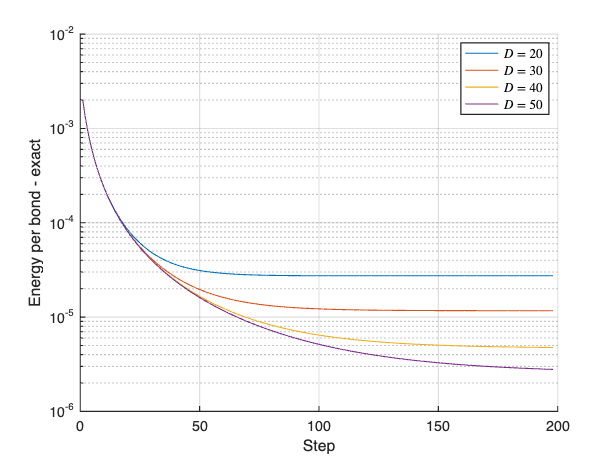


% for Heisenberg model
figure;
legs = cell([1 size(Eiters,2)]);
hold on;
Eexact = 1/4-log(2);
for itD = (1:size(Eiters,2))
    plot((1:size(Eiters{1,itD},2)-2),(Eiters{1,itD}(3:end)-Eiters{1,itD}(1:end-2))/4-Eexact,'LineWidth',1);
    legs{itD} = ['$D = ', ...
        sprintf('%i',D_list(itD)),'$'];
end
hold off;
set(gca,'YScale','log','LineWidth',1,'FontSize',13);
xlabel('Step');
ylabel('Energy per bond - exact');
legend(legs{:},'Interpreter','latex');
grid on;

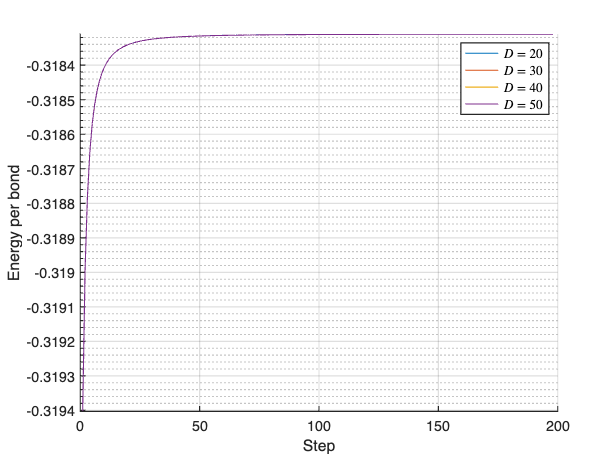

% for Ising model
figure;
legs = cell([1 size(Eiters,2)]);
hold on;
for itD = (1:size(Eiters,2))
    plot((1:size(Eiters{2,itD},2)-2),(Eiters{2,itD}(3:end)-Eiters{2,itD}(1:end-2))/4,'LineWidth',1);
    legs{itD} = ['$D = ', ...
        sprintf('%i',D_list(itD)),'$'];
end
hold off;
set(gca,'YScale','log','LineWidth',1,'FontSize',13);
xlabel('Step');
ylabel('Energy per bond');
legend(legs{:},'Interpreter','latex');
grid on;

% compare with iTEBD
% if you compare the result with that of iTEBD (Tutorial 10.1) for
% Heisenberg model, you can see that iDMRG method converges much faster.
% that is because the eigensolver is efficient and the trial wavefunction
% is relevant.



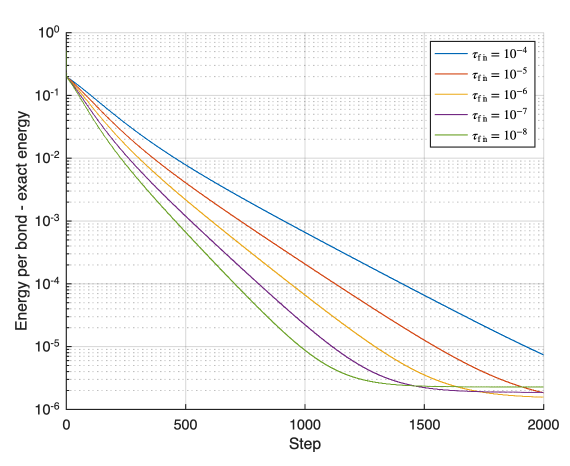

## c)

Verify the claim in Ref. 1 that the trial wave function used in the step 4 of Fig. 1 is a good choice, by computing the fidelity $1-\langle \;\Psi {\;}_n^{\textrm{trial}} |\Psi {\;}_n \rangle \;$. Make a plot similar to Fig. 2 for the Heisenberg model. 						

	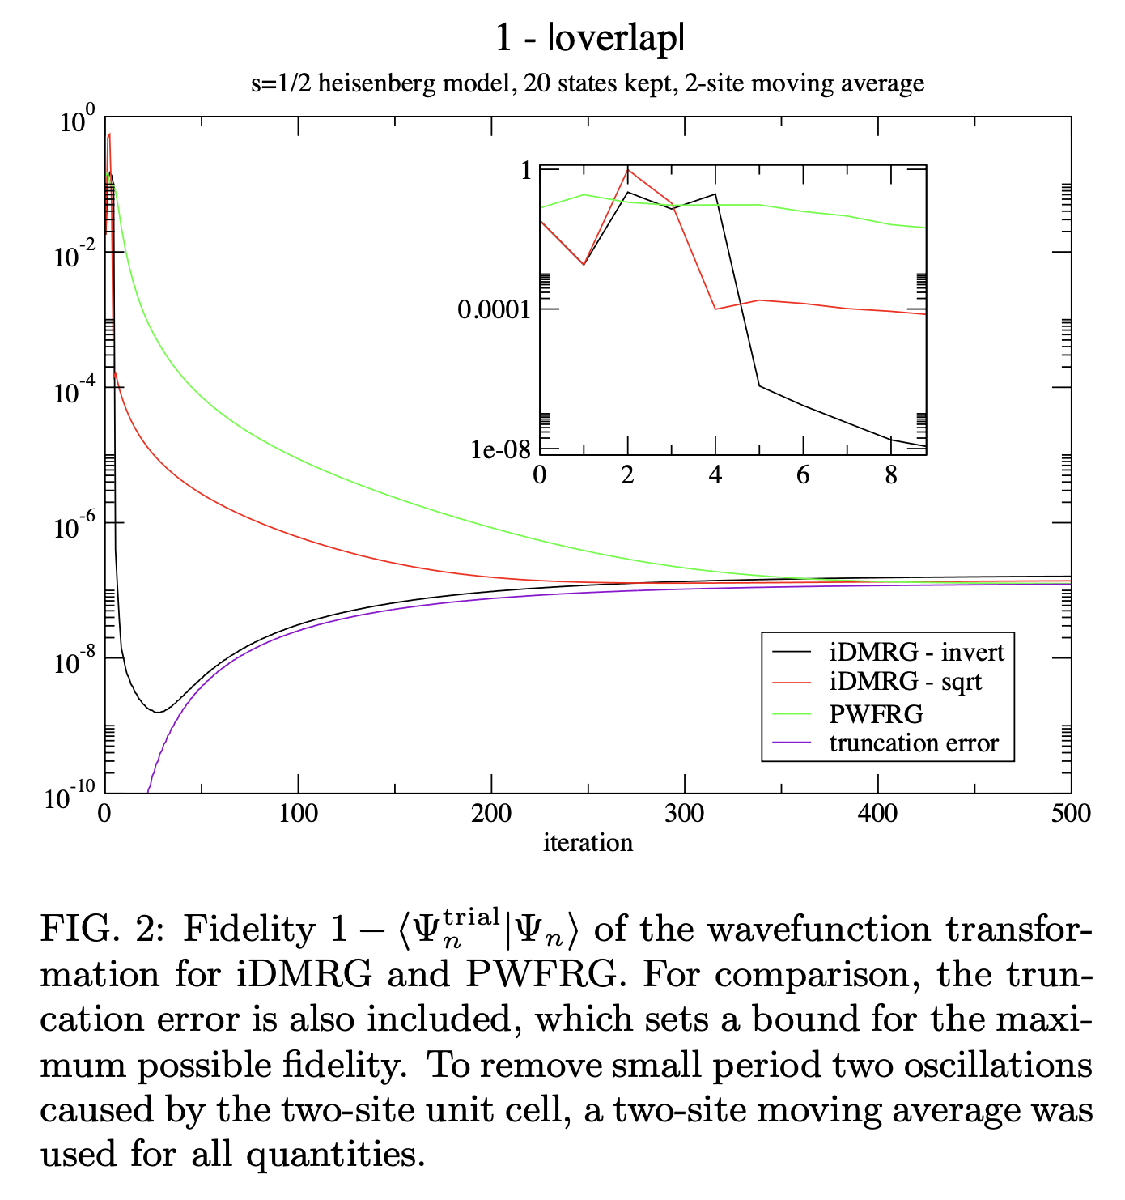

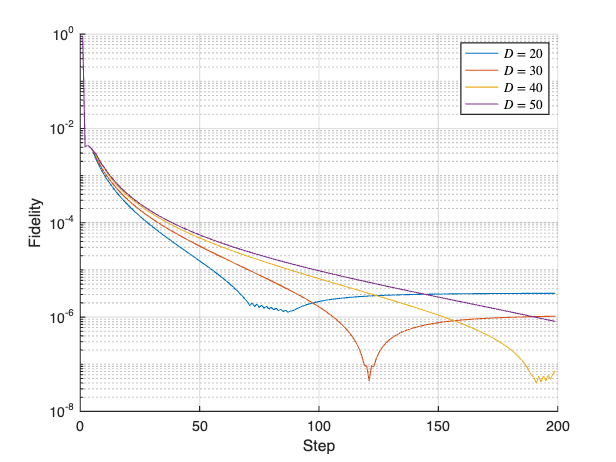

% for Heisenberg model
figure;
legs = cell([1 size(Fid_iters,2)]);
hold on;
for itD = (1:size(Fid_iters,2))
    plot((1:size(Fid_iters{1,itD},2)-1),(Fid_iters{1,itD}(2:end)+Fid_iters{1,itD}(1:end-1)),'LineWidth',1);
    legs{itD} = ['$D = ', ...
        sprintf('%i',D_list(itD)),'$'];
end
hold off;
set(gca,'YScale','log','LineWidth',1,'FontSize',13);
xlabel('Step');
ylabel('Fidelity');
legend(legs{:},'Interpreter','latex');
grid on;


% for Ising model
figure;
legs = cell([1 size(Fid_iters,2)]);
hold on;
for itD = (1:size(Fid_iters,2))
    plot((1:size(Fid_iters{2,itD},2)-1),(Fid_iters{2,itD}(2:end)+Fid_iters{2,itD}(1:end-1)),'LineWidth',1);
    legs{itD} = ['$D = ', ...
        sprintf('%i',D_list(itD)),'$'];

end
hold off;
set(gca,'YScale','log','LineWidth',1,'FontSize',13);
xlabel('Step');
ylabel('Fidelity');
legend(legs{:},'Interpreter','latex');
grid on;

## d)

Analyze the behavior of iDMRG for the Ising model at the critical point $\lambda$=1/2 by studying the spectrum of the transfer operator [see Eq. (28)]. Make a plot similar to Fig. 4. 							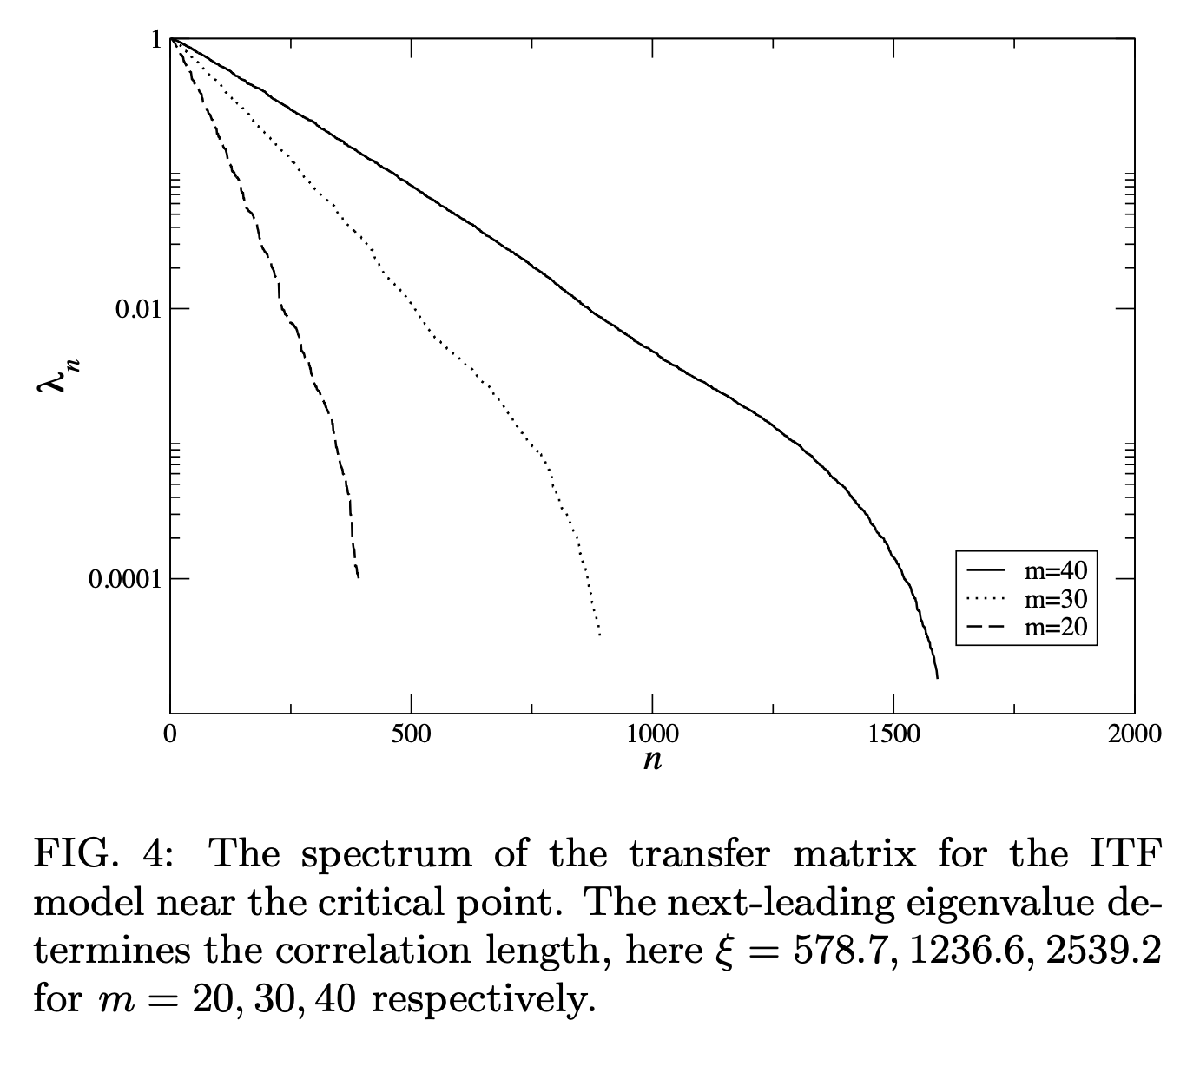		

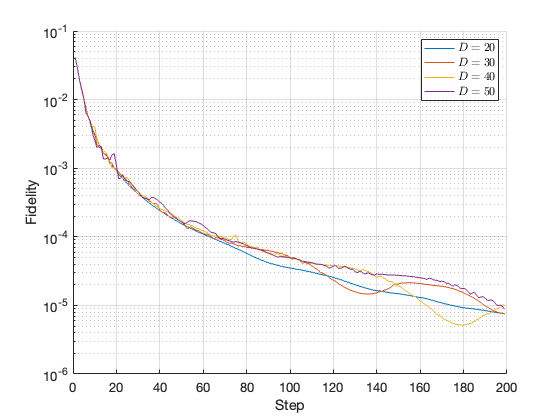

% for Ising model
figure;
legs = cell([1 size(Spect,2)]);
hold on;
for itD = (1:size(Spect,2))
    plot((1:size(Spect{2,itD},1)),(Spect{2,itD}),'LineWidth',1);
    legs{itD} = ['$D = ', ...

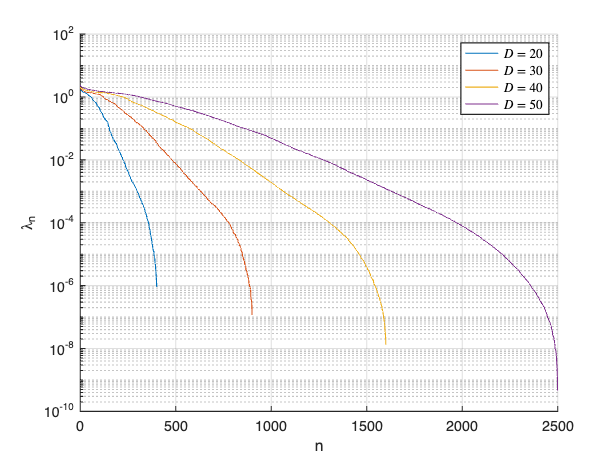

        sprintf('%i',D_list(itD)),'$'];
end
hold off;
set(gca,'YScale','log','LineWidth',1,'FontSize',13);
xlabel('n');
ylabel('\lambda_n');
legend(legs{:},'Interpreter','latex');
grid on;